# Clasificación del Reactor

## 0 Limpieza

clear
clc

## 1 Importación de datos

Lectura de datos

data=readtable("Reactor_Agitado.csv")

data = 120×4 table
    Densidad_kg_m3    Viscosidad_Pa_s     RPM       Agitador  
    ______________    _______________    ______    ___________

        1030.8           0.0059312        145.2    {'Helice' }
        907.78           0.0072957       94.577    {'Helice' }
        1064.9           0.0032123       245.41    {'Turbina'}
        1030.6           0.0026796       168.05    {'Helice' }
        1026.1           0.0019952       114.87    {'Helice' }
         999.1           0.0034665        223.1    {'Turbina'}
        961.39           0.0010922       295.12    {'Pala'   }
        1085.8           0.0066642       111.56    {'Turbina'}
         989.9           0.0036566       247.56    {'Helice' }
        980.05           0.0026856       240.58    {'Helice' }
        1086.3           0.0018576        80.01    {'Helice' }
        1058.7           

## 2 Organización y Preprocesamiento

Acondicionamiento de Datos

Variables de estímulo

X = data{:, {'Densidad_kg_m3', 'Viscosidad_Pa_s', 'RPM'}}

X = 1.0e+03 *

    1.0308    0.0000    0.1452
    0.9078    0.0000    0.0946
    1.0649    0.0000    0.2454
    1.0306    0.0000    0.1681
    1.0261    0.0000    0.1149
    0.9991    0.0000    0.2231
    0.9614    0.0000    0.2951
    1.0858    0.0000    0.1116
    0.9899    0.0000    0.2476
    0.9800    0.0000    0.2406


Variable de respuesta

Y = data.Agitador

Y = 120×1 cell array
    {'Helice' }
    {'Helice' }
    {'Turbina'}
    {'Helice' }
    {'Helice' }
    {'Turbina'}
    {'Pala'   }
    {'Turbina'}
    {'Helice' }
    {'Helice' }
    {'Helice' }
    {'Turbina'}
    {'Pala'   }
    {'Helice' }
    {'Pala'   }
    {'Helice' }
    {'Turbina'}
    {'Pala'   }
    {'Pala'   }
    {'Turbina'}
    {'Turbina'}
    {'Turbina'}
    {'Helice' }
    {'Pala'   }
    {'Helice' }
    {'Turbina'}
    {'Helice' }
    {'Turbina'}
    {'Pala'   }
    {'Turbina'}


Transformación de la variable de respuesta como categórica ya que ésta es cualitativa

Y = categorical(Y)

Y = 120×1 categorical array
     Helice 
     Helice 
     Turbina 
     Helice 
     Helice 
     Turbina 
     Pala 
     Turbina 
     Helice 
     Helice 
     Helice 
     Turbina 
     Pala 
     Helice 
     Pala 
     Helice 
     Turbina 
     Pala 
     Pala 
     Turbina 
     Turbina 
     Turbina 
     Helice 
     Pala 
     Helice 
     Turbina 
     Helice 
     Turbina 
     Pala 
     Turbina 


Partición de datos para *Validación Cruzada*

cv = cvpartition(length(Y),'HoldOut',0.3); 
idxtrain=training(cv); % Va a cambiar aletoriamente entre diferentes corridas
idxtest=test(cv);     % Va a cambiar aletoriamente entre diferentes corridas
Xtrain = X(idxtrain, :);
Ytrain = Y(idxtrain, :);
Xtest = X(idxtest, :);
Ytest = Y(idxtest, :);

## 4 Creación del modelo

Entrenamiento

% t = templateSVM('KernelFunction','rbf','KernelScale','auto'); % Ajuste con iteración 
% model=fitcecoc(Xtrain, Ytrain,'Learners', t);
model=fitcecoc(Xtrain, Ytrain);

## 5 Evaluación del modelo

Validación

Ypred = predict(model, Xtest);

Precisión

acc=mean(Ypred == Ytest);
fprintf('Precisión: %.2f%%\n', acc*100) % Porcentaje de precisión

Precisión: 36.11%


### Visualización

Matriz de confusión

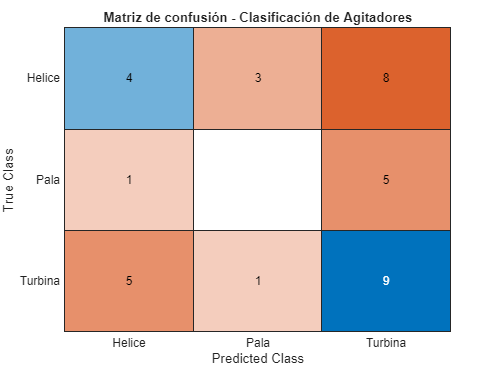

confusionchart(Ytest, Ypred)
title('Matriz de confusión - Clasificación de Agitadores')